clear all, clc, close all;

fid = fopen('../MPC/data/deterministic/results0.json');
raw = fread(fid); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

aTc = val.states.v1;
IPTG = val.states.v2;

sbioloadproject Genetic_Toggle_Switch.sbproj

for i = 1:length(IPTG)
    trigger = strcat('time >= ', int2str((i-1)));
    evnt_IPTG = strcat('IPTG = ', num2str(IPTG(i)), '*u0');
    evnt_aTc = strcat('aTc = ', num2str(aTc(i)), '*u0');
    addevent(m1, trigger, {evnt_aTc, evnt_IPTG});
end

sim = sbiosimulate(m1);

avg_time = (0:1:1200)

avg_time =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


LacI = sim.Data(:,3);
TetR = sim.Data(:,5);

[avg_LacI, avg_TetR] = compute_average_trajectory(LacI, TetR, avg_time)

avg_LacI =   531.6859  533.3476  535.0008  536.6456  538.2820  539.9101  541.5299  543.1414  544.7445  546.3394  547.9261  549.5045  551.0747  552.6368  554.1906  555.7363  557.2739  558.8034  560.3248  561.8381  563.3434  564.8406  566.3298  567.8111  569.2844  570.7497  572.2071  573.6566  575.0982  576.5320  577.9578  579.3759  580.7862  582.1886  583.5833  584.9703  586.3495  587.7210  589.0849  590.4410  591.7895  593.1304  594.4637  595.7894  597.1075  598.4181  599.7212  601.0167  602.3048  603.5854


avg_TetR =   293.8152  293.5992  293.3845  293.1711  292.9590  292.7481  292.5386  292.3303  292.1233  291.9176  291.7131  291.5099  291.3079  291.1072  290.9078  290.7096  290.5127  290.3170  290.1225  289.9293  289.7373  289.5466  289.3571  289.1688  288.9817  288.7958  288.6112  288.4278  288.2455  288.0645  287.8847  287.7061  287.5287  287.3524  287.1774  287.0035  286.8308  286.6593  286.4890  286.3199  286.1519  285.9850  285.8194  285.6549  285.4915  285.3293  285.1683  285.0084  284.8496  284.6920


LacI_ref = 750;
TetR_ref = 300;

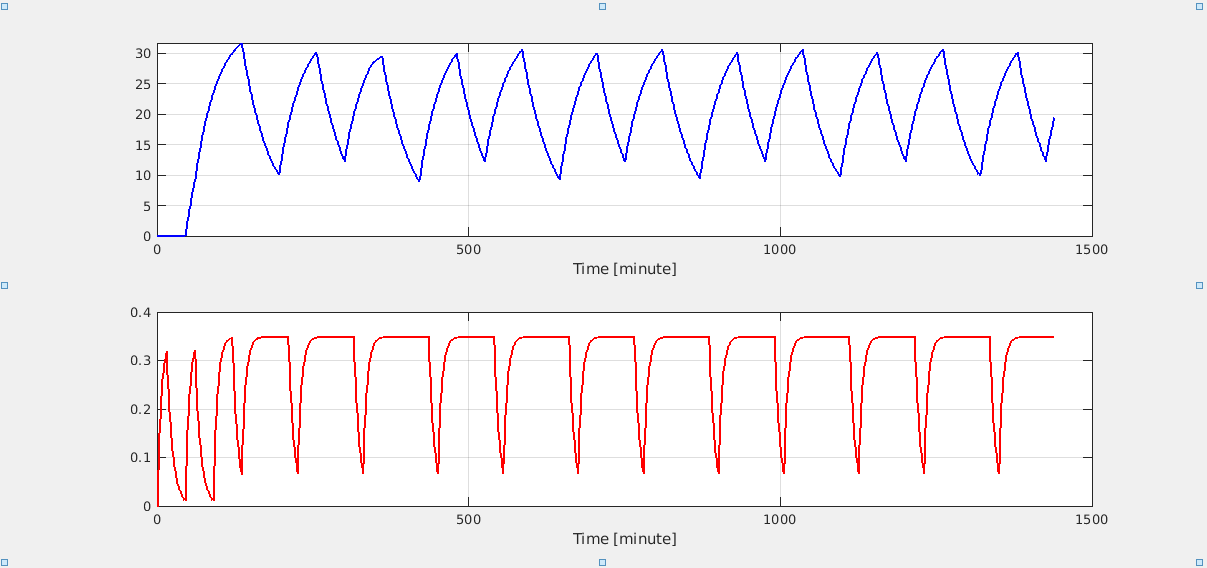

close all;
figure(1);
clf reset
plotbrowser('on');
title('Inputs');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,6), 'DisplayName','aTc');
set(pl,'linewidth',2, 'Color', 'b');
xlabel('Time [minute]');
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,1), 'DisplayName','IPTG');
set(pl,'linewidth',2, 'Color', 'r');
xlabel('Time [minute]');
grid

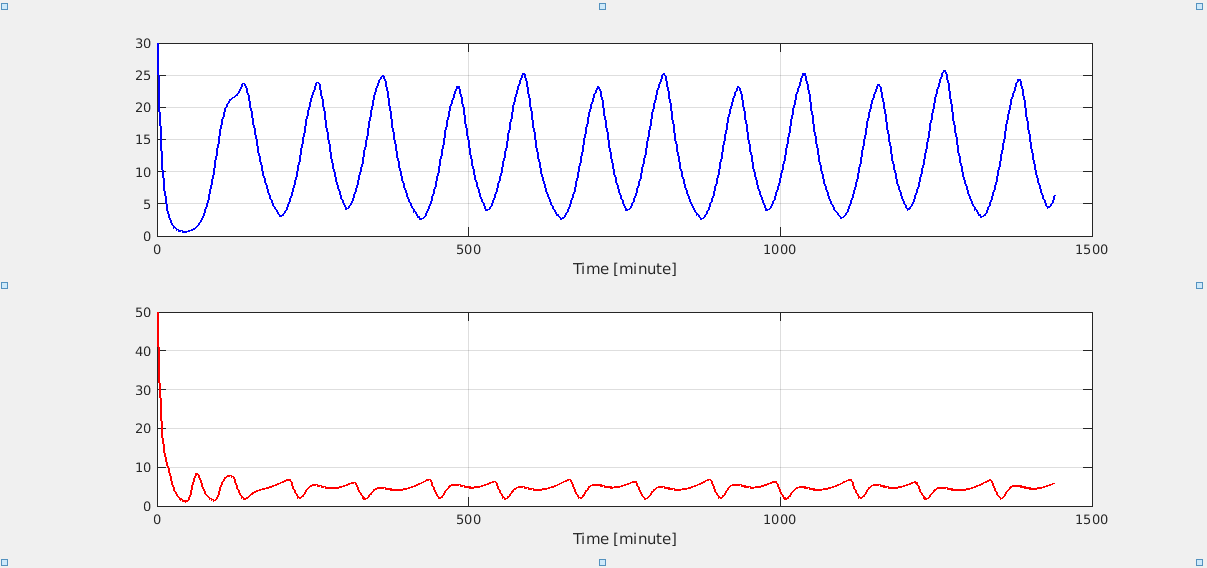

figure(2);
clf reset
plotbrowser('on');
title('mRNAs');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,2), 'DisplayName','mRNA LacI');
set(pl,'linewidth',2, 'Color', 'b');
xlabel('Time [minute]');
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,4), 'DisplayName','mRNA_TetR');
set(pl,'linewidth',2, 'Color', 'r');
xlabel('Time [minute]');
grid

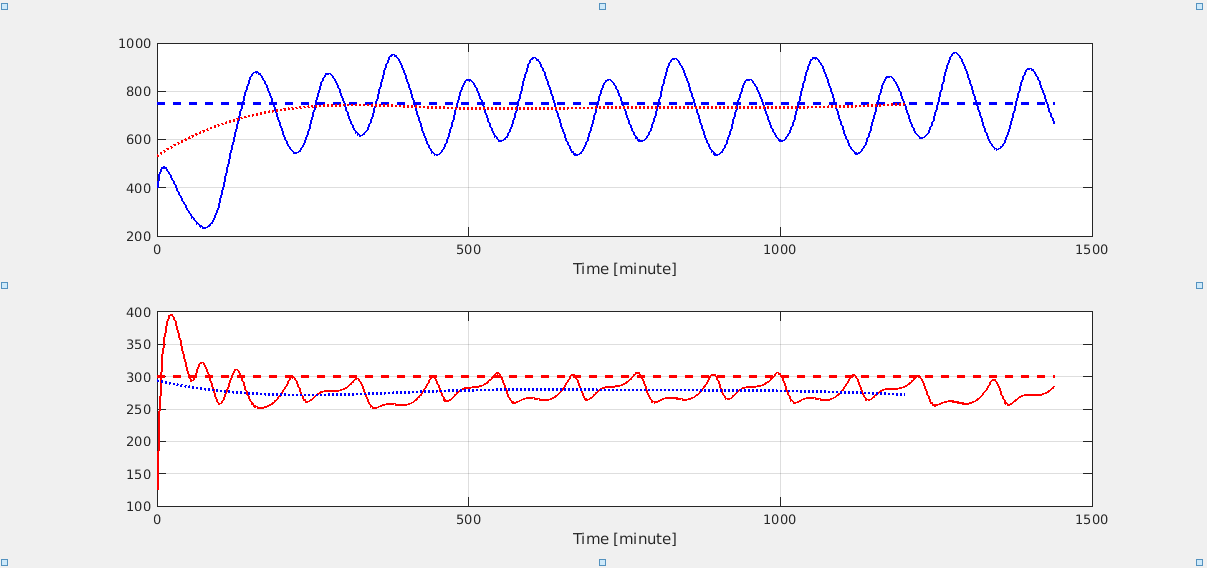

figure(3);
clf reset
plotbrowser('on');
title('Proteins');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,3), 'DisplayName','LacI');
set(pl,'linewidth',2, 'Color', 'b');
hold on
pl = plot(sim.Time, LacI_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', '--');
pl = plot(avg_time, avg_LacI, 'DisplayName','Average LacI');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,5), 'DisplayName','TetR');
set(pl,'linewidth',2, 'Color', 'r');
hold on
pl = plot(sim.Time, TetR_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', '--');
pl = plot(avg_time, avg_TetR, 'DisplayName','Average TetR');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

[ISE,ITAE] = compute_performance_metrics(avg_LacI, avg_TetR, LacI_ref, TetR_ref)

ISE = 12.2279

ITAE = 5.7879e+04